## **Lab 9 Problem 1**

format long e

Vandermonde Matrix with $n+1$datapoints implying $n$-th degree polynomials. 


$$V=\left\lbrack \begin{array}{cccc}
1 & x_0  & \cdots  & x_0^n \\
1 & x_1  & \cdots  & x_1^n \\
\vdots  & \vdots  & \ddots  & \vdots \\
1 & x_n  & \cdots  & x_n^n 
\end{array}\right\rbrack$$


### **Lab 4**

**a)**

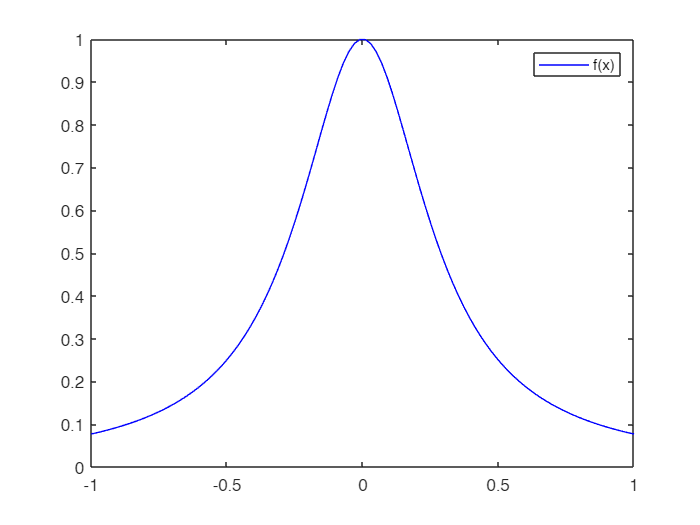

f = @(x) 1./(1+(12*x.^2));
x = linspace(-1, 1, 100);

plot(x, f(x), 'b');
legend("f(x)");

**b), c)**

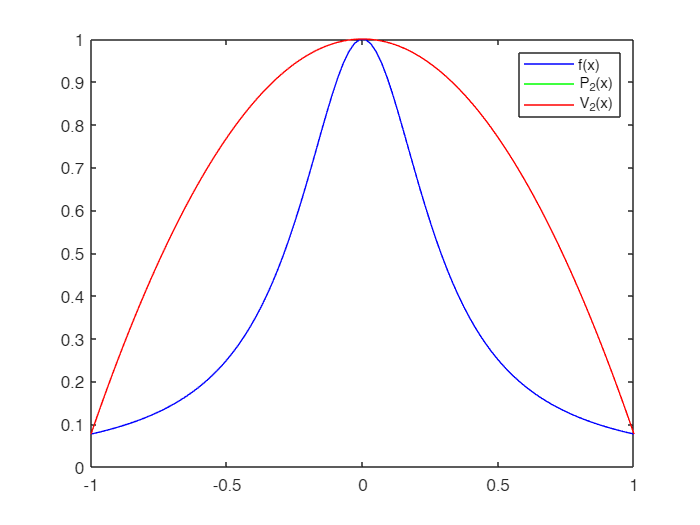

x0 = -1;
x1 = 0;
x2 = 1;

L0 = @(x) ( (x-x1).*(x-x2)  ) / ( (x0-x1).*(x0-x2) );
L1 = @(x) ( (x-x0).*(x-x2)  ) / ( (x1-x0).*(x1-x2) );
L3 = @(x) ( (x-x0).*(x-x1)  ) / ( (x2-x0).*(x2-x1) );

P2 = @(x) (L0(x) * f(x0)) + (L1(x) * f(x1)) + (L3(x) * f(x2));

% augmented matrix
V_2 = [ 
    1 x0 x0.^2 f(x0);
    1 x1 x1.^2 f(x1);
    1 x2 x2.^2 f(x2)
];

% vandemonke
V_2_UPPER = GaussianElimPP(V_2);
V_2_consts = BackSub(V_2_UPPER);

V_2_ploy = @(x) V_2_consts(1) + x.*V_2_consts(2) + (x.^2).*(V_2_consts(3));

plot(x, f(x), 'b', x, P2(x), 'g', x, V_2_ploy(x), 'r');
legend("f(x)", "P_2(x)", "V_2(x)");

**d), e)**

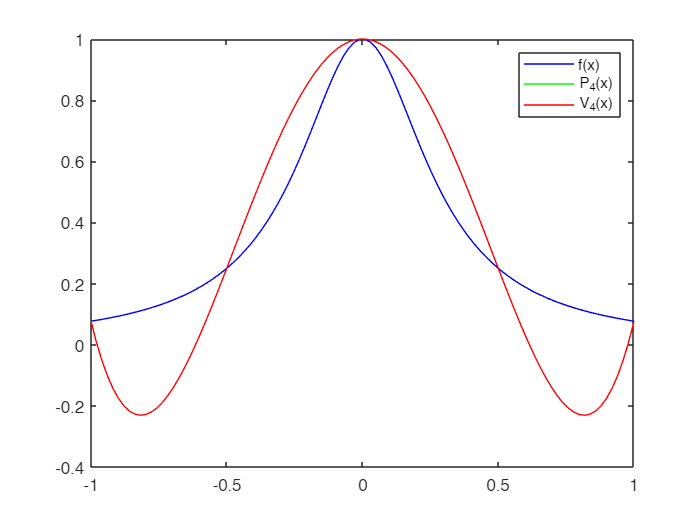

x0 = -1;
x1 = -0.5;
x2 = 0;
x3 = 0.5;
x4 = 1;

L0 = @(x) ( (x-x1).*(x-x2).*(x-x3).*(x-x4)  ) / ( (x0-x1).*(x0-x2).*(x0-x3).*(x0-x4) );
L1 = @(x) ( (x-x0).*(x-x2).*(x-x3).*(x-x4)  ) / ( (x1-x0).*(x1-x2).*(x1-x3).*(x1-x4) );
L2 = @(x) ( (x-x0).*(x-x1).*(x-x3).*(x-x4)  ) / ( (x2-x0).*(x2-x1).*(x2-x3).*(x2-x4) );
L3 = @(x) ( (x-x0).*(x-x1).*(x-x2).*(x-x4)  ) / ( (x3-x0).*(x3-x1).*(x3-x2).*(x3-x4) );
L4 = @(x) ( (x-x0).*(x-x1).*(x-x2).*(x-x3)  ) / ( (x4-x0).*(x4-x1).*(x4-x2).*(x4-x3) );

P4 = @(x) (L0(x) * f(x0)) + (L1(x) * f(x1)) + (L2(x) * f(x2)) + (L3(x) * f(x3)) + (L4(x) * f(x4));

V_4 = [ 
    1 x0 x0.^2 x0.^3 x0.^4 f(x0);
    1 x1 x1.^2 x1.^3 x1.^4 f(x1);
    1 x2 x2.^2 x2.^3 x2.^4 f(x2);
    1 x3 x3.^2 x3.^3 x3.^4 f(x3);
    1 x4 x4.^2 x4.^3 x4.^4 f(x4)
];

% vandemonke
V_4_UPPER = GaussianElimPP(V_4);
V_4_consts = BackSub(V_4_UPPER);

V_4_ploy = @(x) V_4_consts(1) + x.*V_4_consts(2) + (x.^2).*(V_4_consts(3)) + (x.^3).*(V_4_consts(4)) + (x.^4).*(V_4_consts(5));

plot(x, f(x), 'b', x, P4(x), 'g', x, V_4_ploy(x), 'r');
legend("f(x)", "P_4(x)", "V_4(x)");

**f)**

diff = abs(f(0.45) - V_2_ploy(0.45));
sprintf("V2 v. Actual Function: The absolute difference is %s", diff)

ans = "V2 v. Actual Function: The absolute difference is 5.215317e-01"


diff = abs(f(0.45) - V_4_ploy(0.45));
sprintf("V4 v. Actual Function: The absolute difference is %s", diff)

ans = "V4 v. Actual Function: The absolute difference is 7.431827e-02"


diff = abs(f(0.45) - P2(0.45));
sprintf("V2 v. P2 Lagrange: The absolute difference is %s", diff)

ans = "V2 v. P2 Lagrange: The absolute difference is 5.215317e-01"


diff = abs(f(0.45) - P4(0.45));
sprintf("V4 v. P4 Lagrange: The absolute difference is %s", diff)

ans = "V4 v. P4 Lagrange: The absolute difference is 7.431827e-02"

#### **Analysis**

Given that the polynomials generated by the Vandermonde Matrix are different from the interpolation polynomials and interpolation polynomials are unique, the Vandermonde Matrix Polynomial is likely off. Moreover we notice that there are more operations used to **obtain** Vandermonde Matrix since we are commiting operations in the order of $O\left(n^3 \right)$ by reducing the matrix and back substituting. 

While this is **not **a concrete line of reasoning, I think that using a **Linear System** represent a $n$-th function and approximating it will cause errors since we are losing information with linear representations. 

**Elim Function**

% gives back a UPPER matrix to be backsubbed later

function U = GaussianElimPP(M)
    [L, W] = size(M);
    
    %ignore last two cols 
    for col = 1:W-2
        % perform partial pivot swap
        row_max = M(col, col);
        row_max_idx = col;

        for row = col:L
            % the abs prevents a 0 from becoming a pivot entry
            if abs(M(row, col)) > row_max
                row_max = M(row, col);
                row_max_idx = row;
            end
        end

        if row_max == 0
            fprintf("Unable to find pivot for col=%d", col);
        end

        %after finding largest entry perform swap
        temp = M(col, :);
        M(col, :) = M(row_max_idx, :);
        M(row_max_idx, :) = temp;
        % at this point the partial pivot is done
        
        for row = col + 1:L
            m_ij = M(row, col) ./ row_max; % no need to fetch row_max its saved
            M(row, :) = M(row, :) - m_ij*M(col, :); %vector op to make life easier
        end
        
    end

    U = M;

end

**Back Sub**

function x = BackSub(A)
    [row, col] = size(A);
    x = zeros(1, row); % needs to be of row size

    x(row) = A(row, col) ./ A(row, col - 1);
  
    for i = row-1:-1:1
        x(i) = A(i, col);
        for j = i+1:col-1
            x(i) = x(i) - (A(i, j).*x(j));
        end
        x(i) = x(i) ./ A(i, i);
    end
end